# General linear model

This tutorial teaches how to use a linear systems approach to predict the blood oxygen level dependent (BOLD) response to a stimulus. It includes instructions for coding an experiment's stimulus presentation, combining the stimulus predictors with a hemodynamic response function, and comparing various models to determine the amount of variance in the signal that each model explains.

- **Class**:     Psych 204A

- **Tutorial**:  GLM linear model

- **Author**:   Anothony Stigliani, Insub kim

- **Date**:       01.23.2023

We will create and compare two models:

model1: Uses stimulus duration as a predictor

model2: Uses stimulus duration, onset and offset as predictors

**References:**

https://mriquestions.com/general-linear-model.html

Horiguchi, H., Nakadomari, S., Misaki, M., & Wandell, B. A. (2009). Two temporal channels in human V1 identified using fMRI. *Neuroimage*, *47*(1), 273-280.

Stigliani, A., Weiner, K. S., & Grill-Spector, K. (2015). Temporal processing capacity in high-level visual cortex is domain specific. *Journal of Neuroscience*, *35*(36), 12412-12424.

Kim, I. Kupers, E., Garikoitz, L., Shim, W., & Grill-Spector, K. (2022). A new computational framework for estimating spatio-temporal population receptive fields in human visual cortex. Conference on cognitive computational neuroscience.

## Load and inspect data 

% The tSeriesV1 vector contains fMRI data recorded from the primiary visual area (V1).
% the data was collected while a subject was viewing a set of different
% stimuli.
load('./data/tSeriesV1.mat')

% Each number corresponds to a point in time (with a time resolution of 1 second).
numMeasurement = size(data,1);
fprintf('Number of measurements: %d (seconds) \n', ...
    numMeasurement);

Number of measurements: 276 (seconds) 


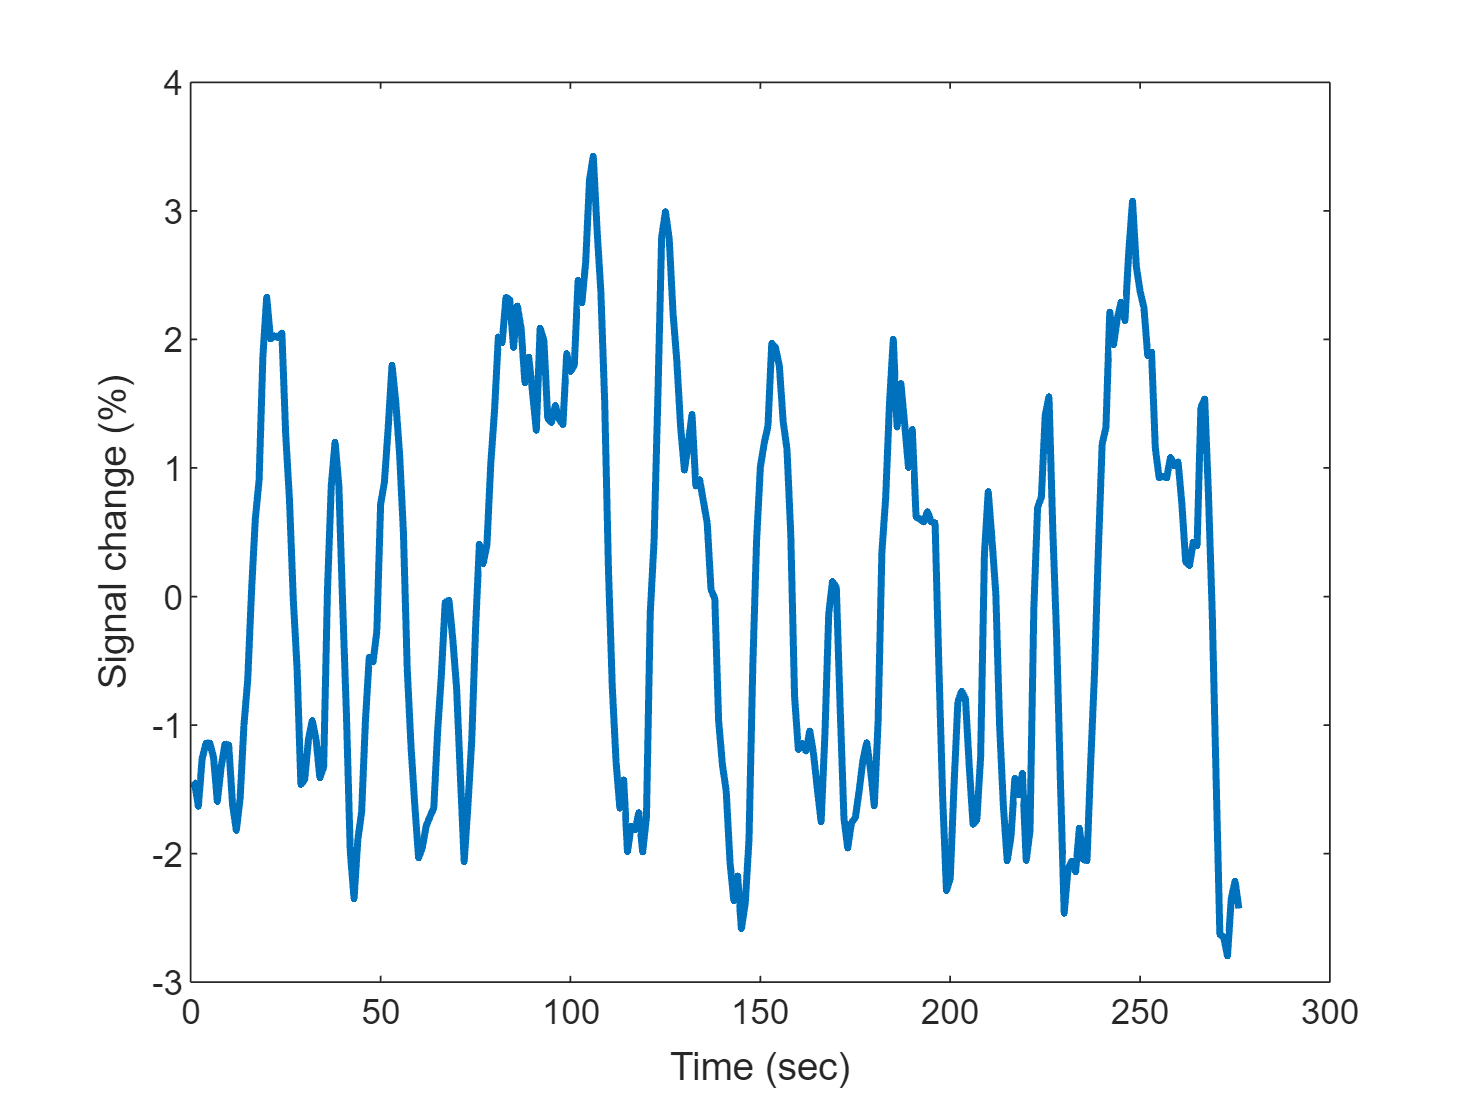

% The x-axis is time in seconds, and the y values are in units of percent signal change
figure;
plot(data,'LineWidth',2);
xlabel('Time (sec)');
ylabel('Signal change (%)');

## Stimulus 

View how the stimulus was presented:

- The subject viewed a total of 12 textures

- Each texture was displayed continuously for one of  1, 2, 4, 8, 15, or 30 seconds.

- Each texture was presented in a random order.

- There was a 12s baseline period after the offset of each texture.

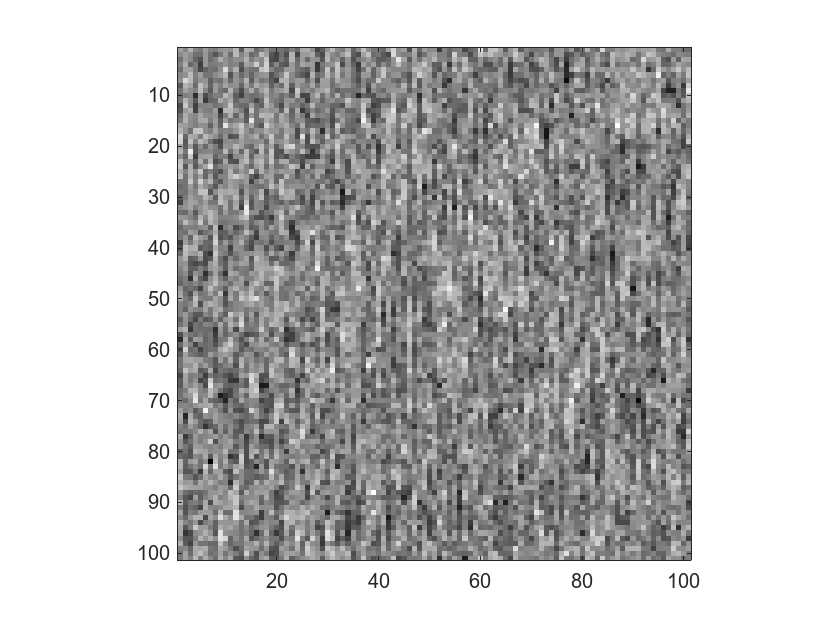

figure;
load("stim.mat")
colormap gray;
for i = 1:100 % play the first 100 seconds 
    imagesc(stim(:,:,i)); axis square; 
    drawnow; pause(0.01); 
end

### Stimulus timing information

% I have extracted stimulus onset and offset timings information for you:
load trialOnsetOffset.mat

% The trialOnsets vector contains the onset time of each texture in
% seconds:
trialOnsets = trialOnsetOffset(:,1);

% The trialOffsets vector contains the offset time of each image in seconds
trialOffsets = trialOnsetOffset(:,2);

% tiral duration
trialDurations = trialOffsets-trialOnsets;

% we have 12 trials in total;
numTrials = size(trialOnsets,1);

% View table of onset and offsets
% Each row indicates trial number
% For example, in trial number 3, a stimulus was presented for 4 seconds
% and the stimulus was presented 32 seconds after the start of the
% experiment and was replaced by an isoluminant gray baseline screen at
% 50 seconds after the start of the experiment
table(trialOnsets,trialOffsets,trialDurations)

ans = 12×3 table
    trialOnsets    trialOffsets    trialDurations
    ___________    ____________    ______________

         12             20                8      
         32             34                2      
         46             50                4      
         62             63                1      
         75            105               30      
        117            132               15      
        144            152                8      
        164            165                1      
        177            192               15      
        204            206                2      
        218            222                4      
        234            264               30      


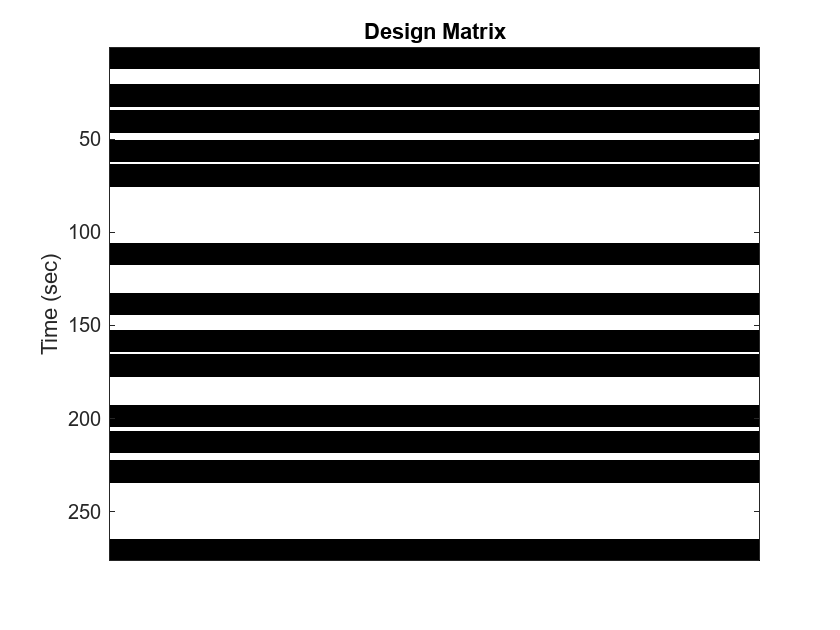

% First let's create a model that considers stimulus duration.
% We'll want to preallocate a matrix of zeros to store these predictors
stimMat = zeros(numMeasurement,1);

% Loop through each of the 12 trials
for t = 1:numTrials
    % And put ones at time points when the stimulus was on
    stimMat(trialOnsets(t,1)+1:trialOffsets(t,1),1) = 1;
end

% You can get a quick sense of what stimMat looks like so far using imagesc
% Each column codes when the stimulus was on and off for a single run
% The rows (TRs) go from top (beginning of experiment) to bottom (end)
figure;
imagesc(stimMat);
colormap('gray'); xticks(''); ylabel('Time (sec)');
title('Design Matrix');

## Hemodynamic Response Function (HRF)

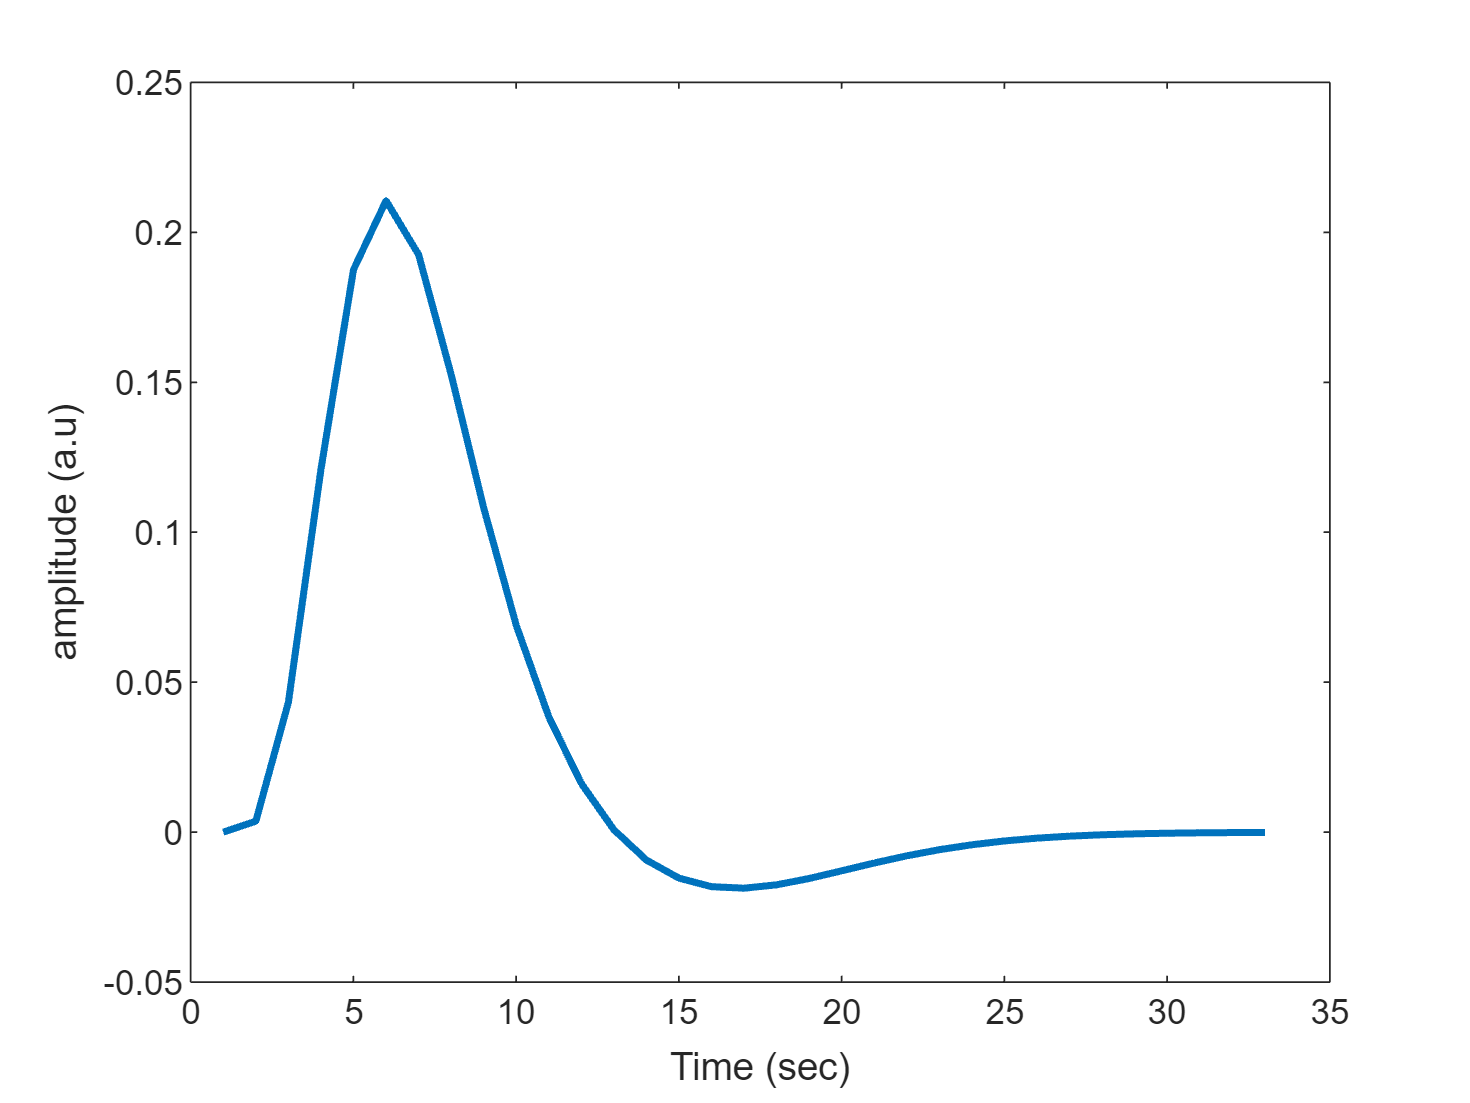

% Next let's sample the SPM Hemodynamic Response Function (HRF) with a 1s
% Repeat Time
% There are multiple ways to compute the HRF in our teachmri repo, here we'll use a default 
% hrf = boyntonHIRF(1:22)
% hrf = DaleBucknerHIRF(1:22,2.25,1.25)
hrf = spm_hrf(1);
plot(hrf,'LineWidth',2); xlabel('Time (sec)'); ylabel('amplitude (a.u)');

## Convolving stimulus timing information with HRF

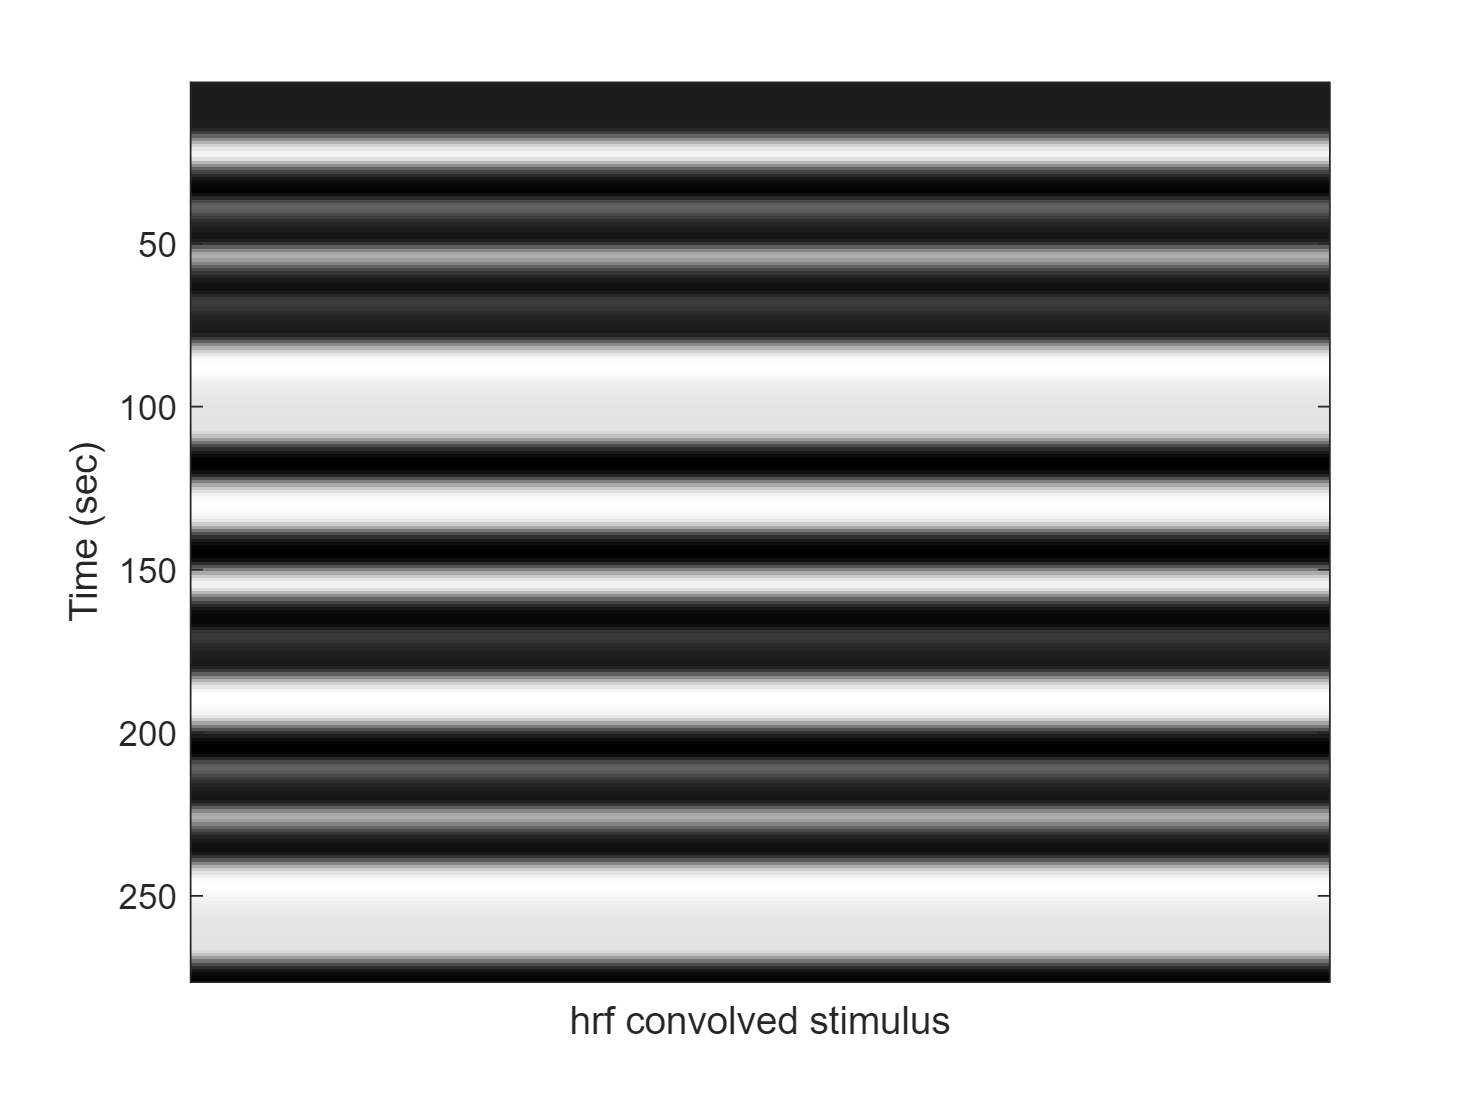

% Now we can convolve the stimulus predictors for each run with this HRF
convMat = zeros(size(stimMat));
% Convolve this stimulus predictor with the HRF
convolvedStim = conv(hrf,stimMat(:,1));

% The convolved predictor extends beyond the duration of the experiment
% Store only the first 276 time points of the convolved stimulus
convMat(:,1) = convolvedStim(1:numMeasurement);

figure; imagesc(convMat); colormap('gray')
xticks(''); xlabel({'HRF convolved stimulus'}); ylabel('Time (sec)')

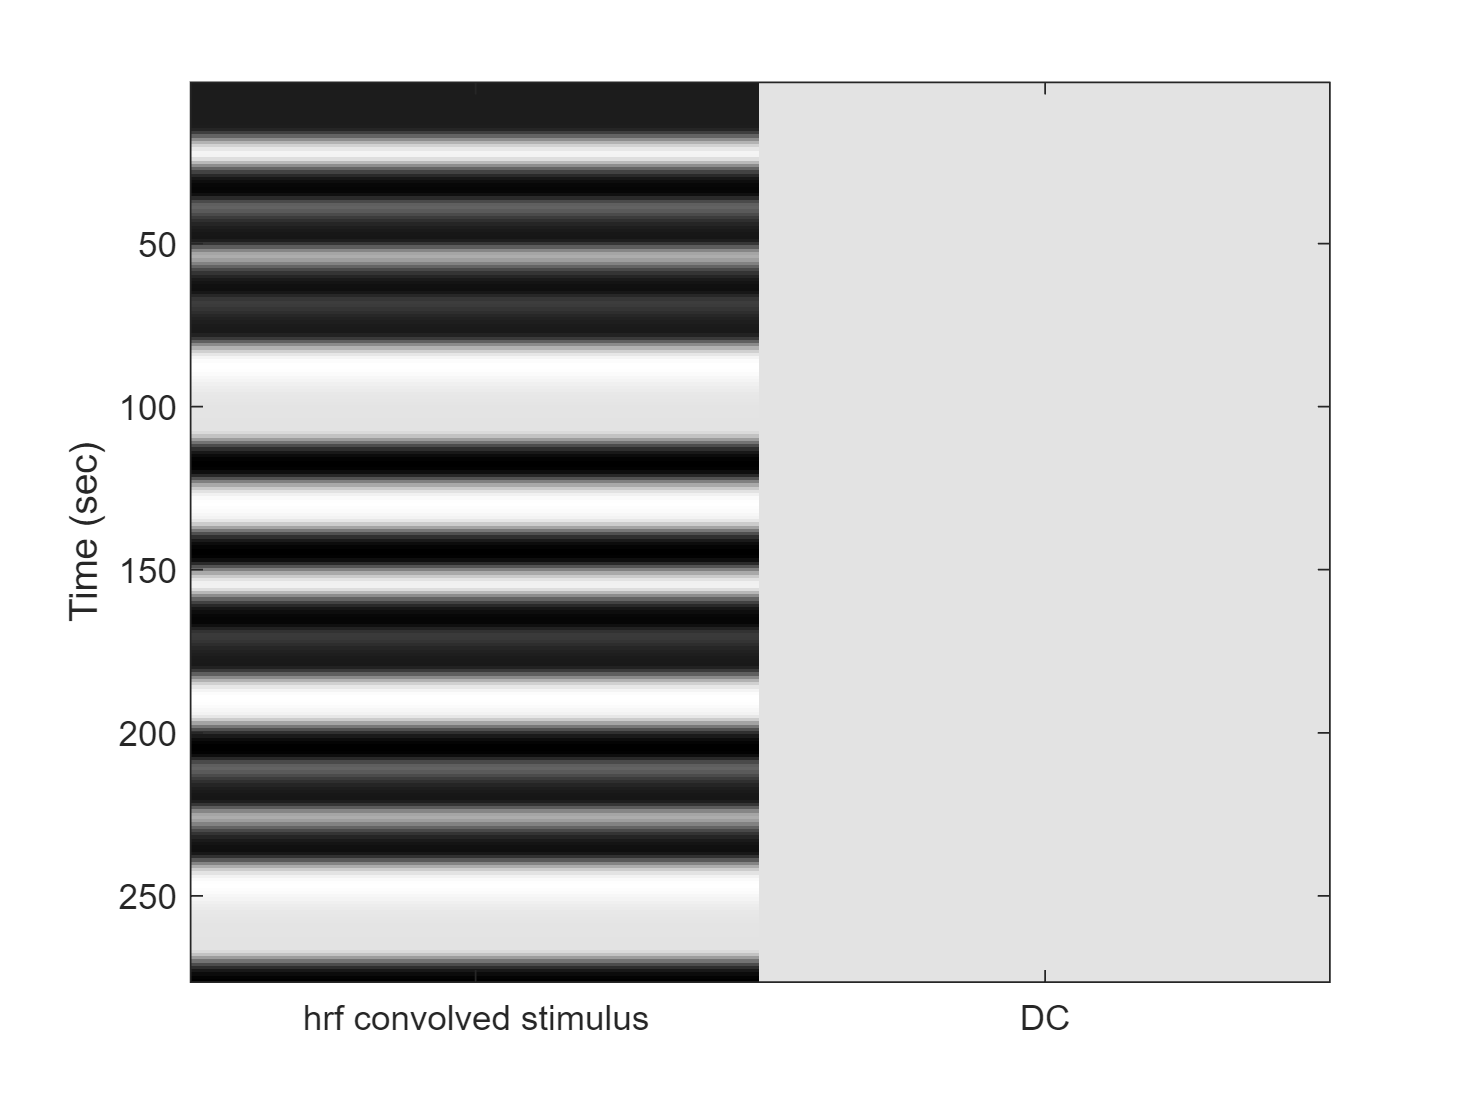

% Finally we'll concatenate the convolved stimulus predictors with DC
% component which captures the mean value of the signal
designMat = zeros(numMeasurement,2);
designMat(:,1) = convMat;

% Concat DC prediction
designMat(:,2) = 1;

% Now the first column in designMat indicates the stimulus and
% Columns 2, indicates the DC component of the signal.
figure; imagesc(designMat); colormap('gray');
xticks([1,2]);
xticklabels({'hrf convolved stimulus','DC'}); ylabel('Time (sec)')

### Plot design matrix for Model 1

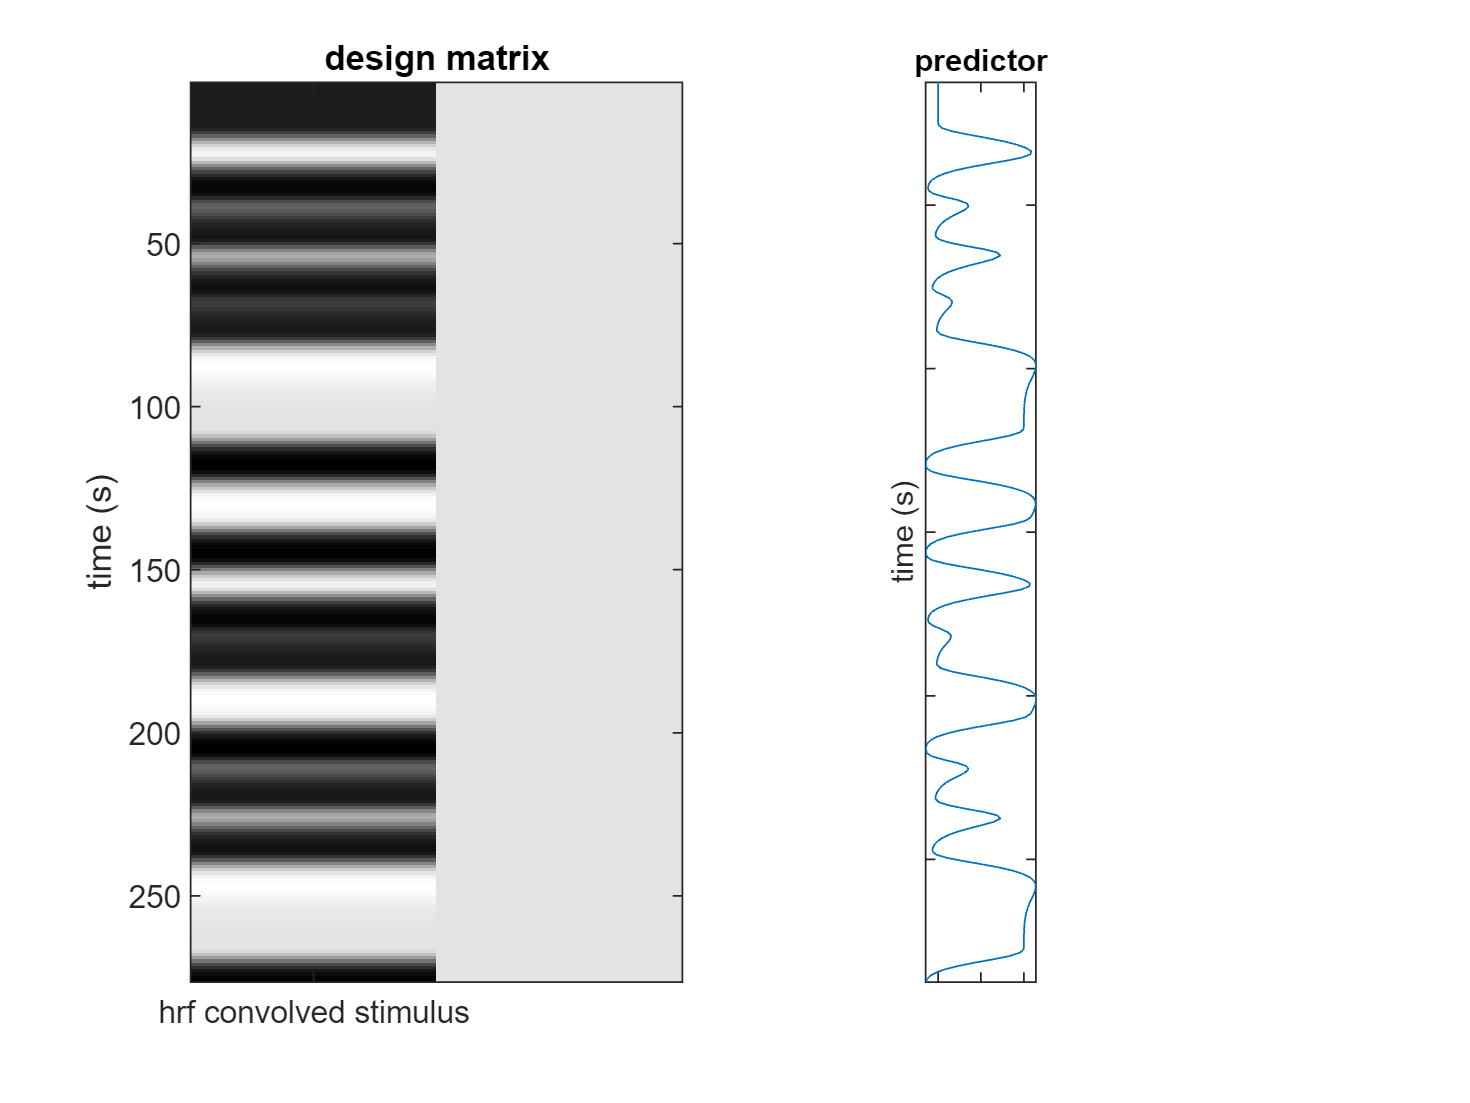

figure('color',[ 1 1 1],'name','design matrix and predictors');
subplot(1,2,1)
imagesc(designMat);colormap(gray(256))
ylabel('time (s)'); title('design matrix');
set(gca,'Xtick', [ 1 2 3 4],'XtickLabel',{'stim' 'R1' 'R2' 'R3'})
set(gca,'Xtick', [ 1],'XtickLabel',{'HRF convolved stimulus','DC'})

subplot (1,8,6)
predictor=reshape(convMat,276*1,1);
h=plot(predictor);
rotate(h,[ 0 0 1],-90); axis('tight'); set(gca,'YtickLabel',[],'XtickLabel',[])
ylabel('time (s)');title('predictor');

## Estimate betas and compute variance explained for Model 1

% With our model and data formatted properly we can now estimate betas
betaWeights = designMat\data;
fprintf('beta weight: %1.2f',betaWeights(1))

beta weight: 2.89

% The first (stimulus) predictor is assigned a beta weight of 2.88

% Now using these beta weights we can see how well our model fits the data
% Multiply the design matrix by the beta weights to generate a prediction
tSeriesPredicted = designMat*betaWeights;
% And then find the difference between this prediction and the actual data
residuals = data-tSeriesPredicted;
% Finally we can compute the proportion of variance explained by the GLM
SStotal = sum((data-mean(data)).^2);
SSerror = sum(residuals.^2);
varExp = 1-SSerror/SStotal

varExp = 0.7440

This means that we're explaining 74.4 percent of the variance in V1!

How could we try to further increase the proportion of the variance explained by the model?

## Code the design matrix for Model 2

We know that neural responses to a sustained stimulus decrease over time.

Most neurons exhibit high firing rates right after stimulus onset, but responses tend to decrease with prolonged presentation of a stimulus.

The offset of a sustained stimulus can also affect neural responses, however stimulus offsets can reduce responses in some neural populations.

To model these effects we will create Model 2, by adding two more predictors to Model 1:

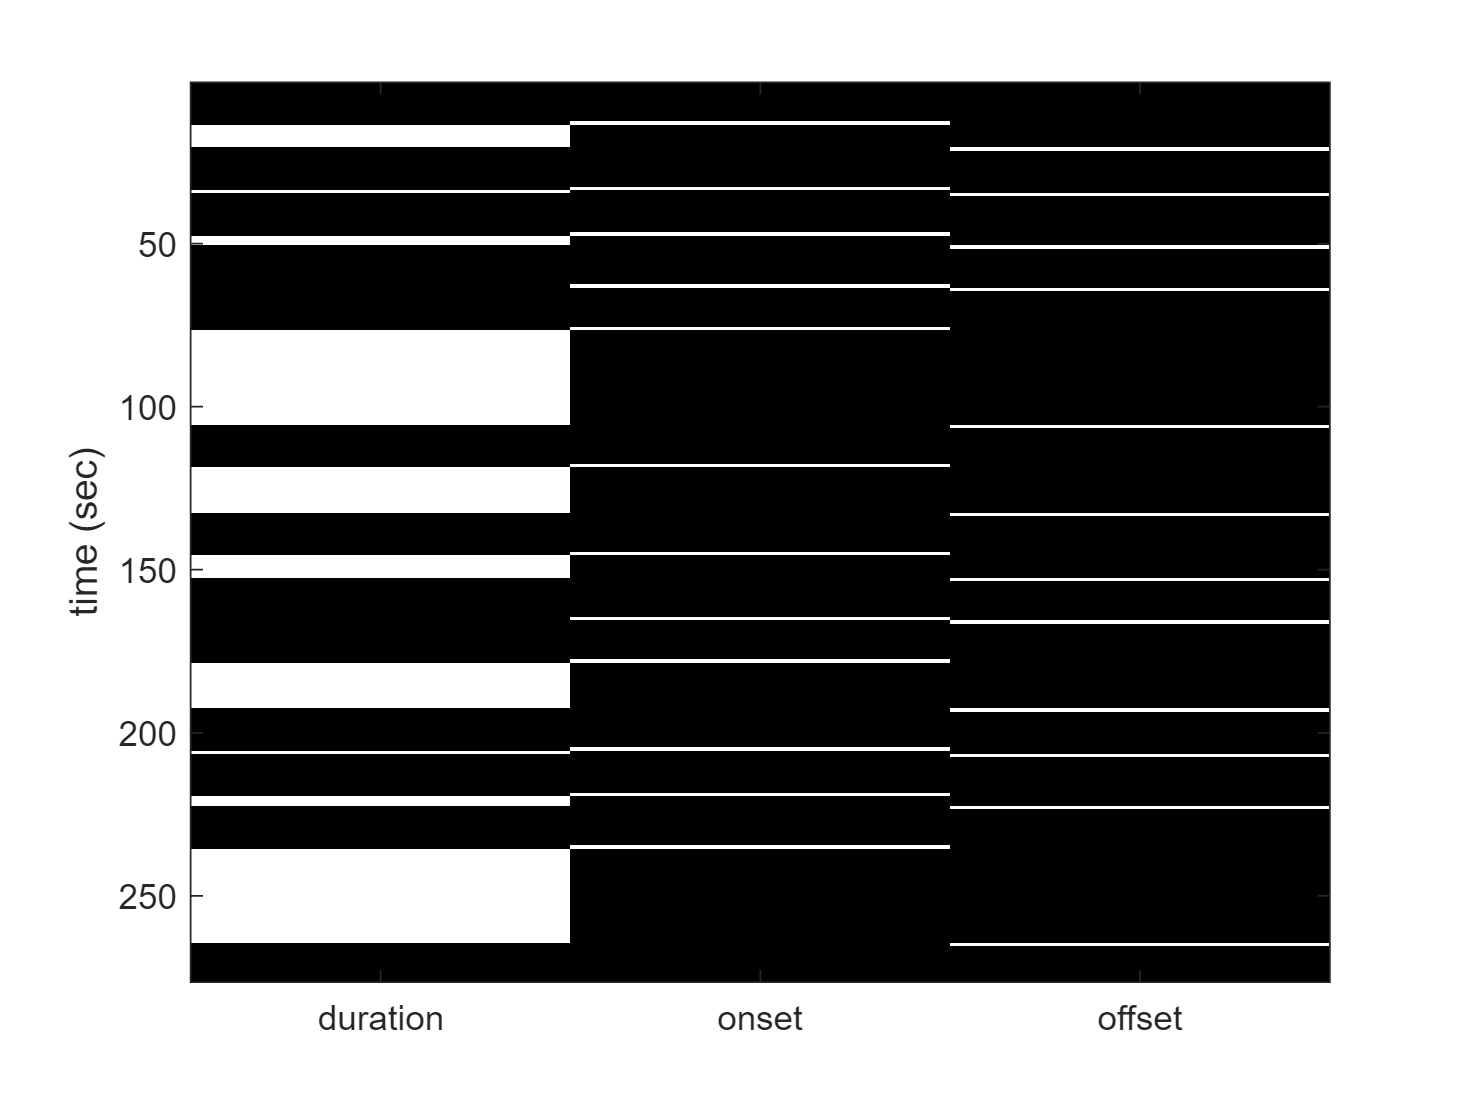

% Model 2 will have three predictors (Sustained, Onset, and Offset)
numPreds = 3;

% The row in the stimulus matrix still represents a the measurment (sec)
% But each of the three columns codes a different predictor now.
stimMat2 = zeros(numMeasurement,numPreds);

% For each of the 12 trials 
for t = 1:numTrials
    % Code when the stimulus is on vs. off in the first predictor
    stimMat2(trialOnsets(t,1)+1:trialOffsets(t,1),1) = 1;
    % Code the onset of each texture in the second predictor
    stimMat2(trialOnsets(t,1)+1,2) = 1;
    % Make sure the first predictor isn't turned on at the same time
    stimMat2(trialOnsets(t,1)+1,1) = 0;
    % Code the offset of each texture in the third predictor
    stimMat2(trialOffsets(t,1)+1,3) = 1;
end

% Have a peek at stimulus predictors for each of the three runs
figure; imagesc(stimMat2(:,:,1)); colormap('gray'); % Run 1
set(gca,'Xtick', [ 1,2,3],'XtickLabel',{'duration','onset','offset'});
ylabel('time (sec)');

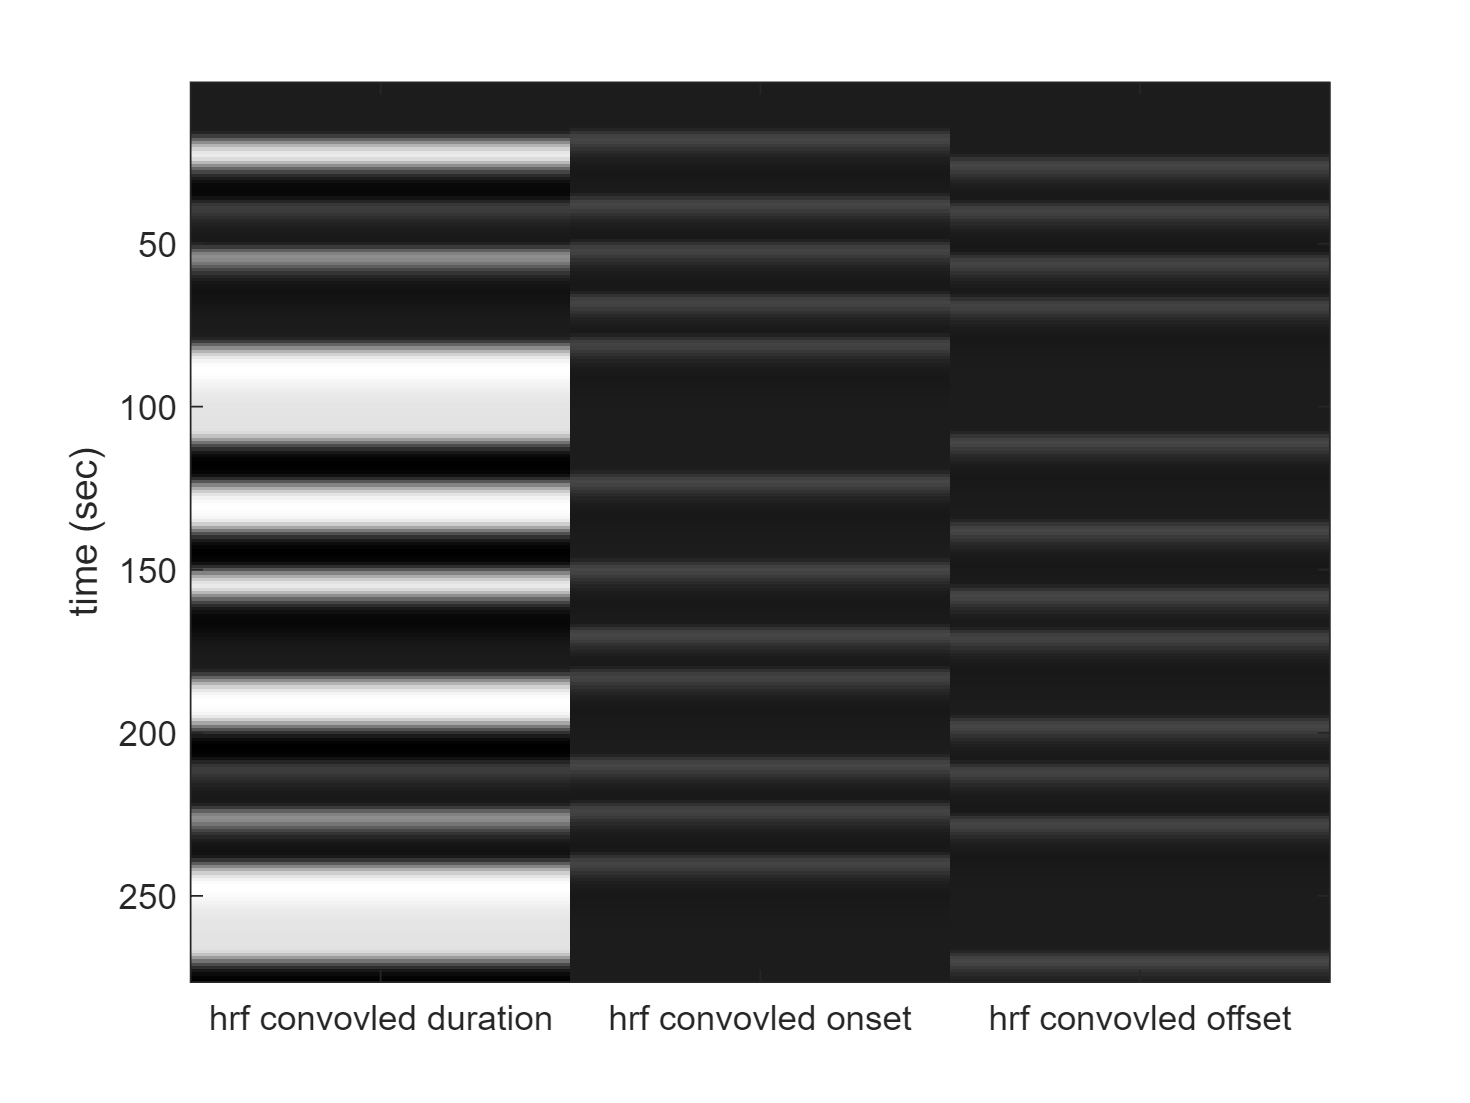

% Now we can convolve stimulus predictors from each run separately
convMat2 = zeros(size(stimMat2));
% For each of the stimulus predictors (Susatined, Onset, Offset)
for p = 1:numPreds
    % Convolve this predictor with the HRF
    convolvedStim = conv(hrf,stimMat2(:,p));
    % Store only the first 276 time points of the convolved response
    convMat2(:,p) = convolvedStim(1:numMeasurement);
end

% Have a peek at convolved predictors for each of the 3 runs
figure; imagesc(convMat2(:,:,1)); colormap('gray'); % Run 1
set(gca,'Xtick', [ 1,2,3],'XtickLabel', ...
    {'HRV convolved duration','HRF convolved onset','HRF convolved offset'})
ylabel('time (sec)');

### Plot design matrix for Model 2

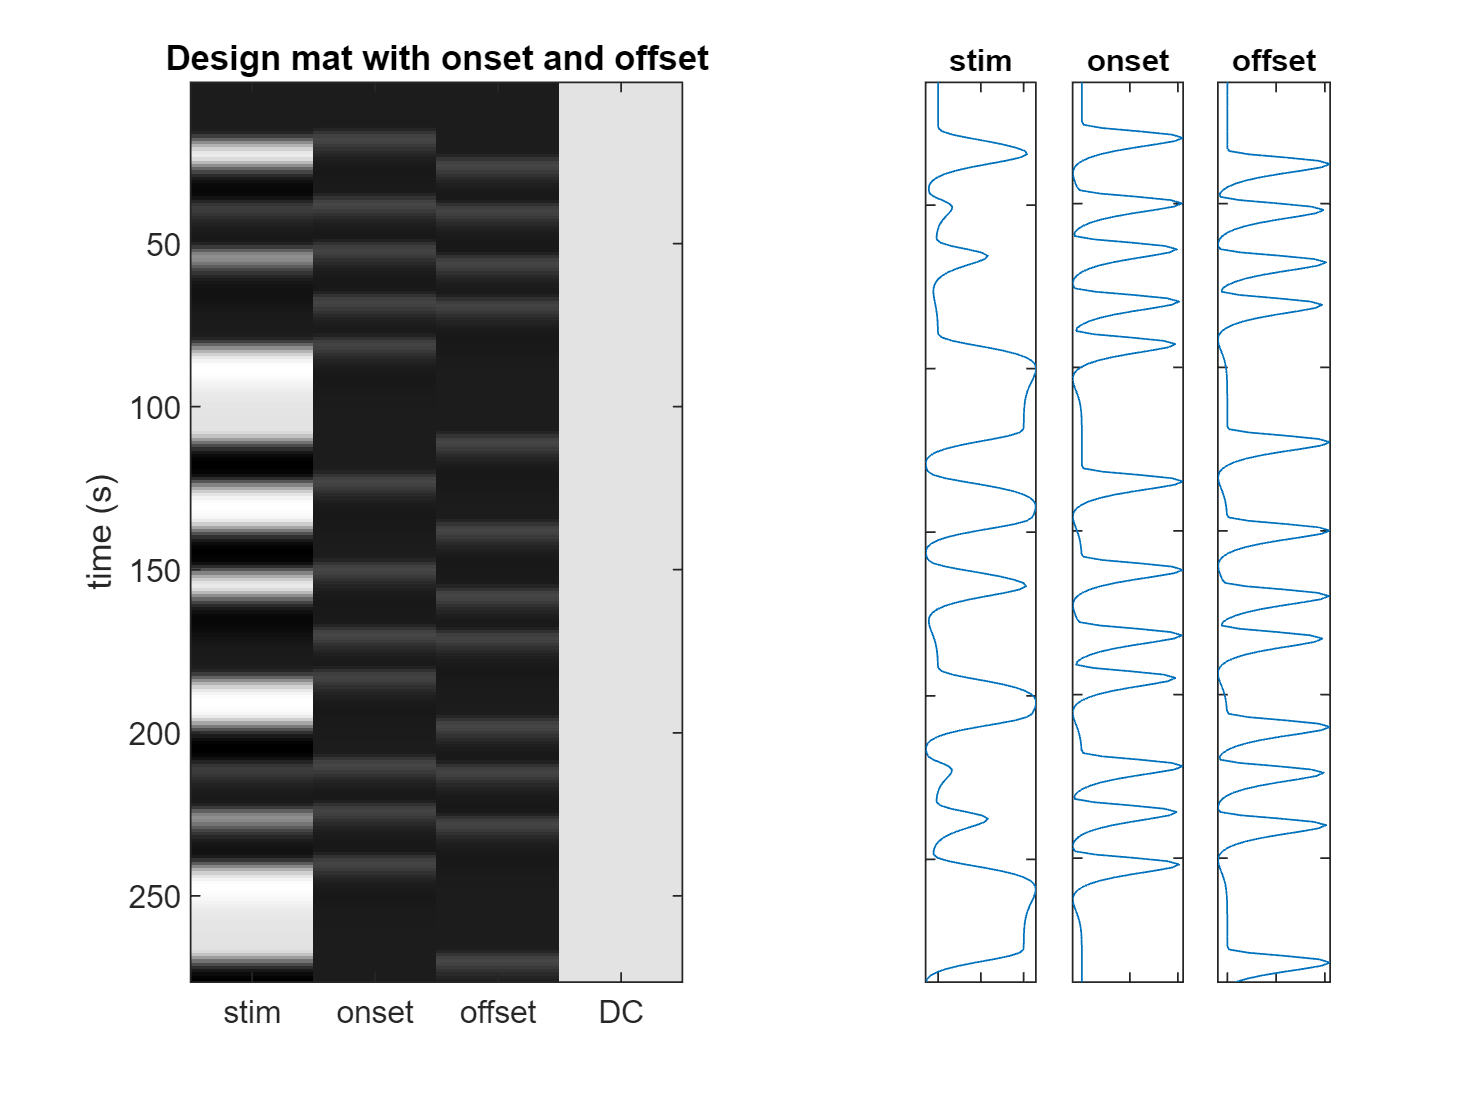

% Finally as we did before, we'll concatenate the convolved stimulus
% predictors with a DC that captures the overall mean value
designMat2 = zeros(numMeasurement,numPreds+1);

% Add the convolved stimulus predictors for this run to designMat2
designMat2(:,1:numPreds) = convMat2;
% And add the DC
designMat2(:,1+numPreds) = 1;

figure('color',[ 1 1 1],'name','design matrix and predictors');
subplot(1,2,1)
imagesc(designMat2);colormap(gray(256))
ylabel('time (s)')
set(gca,'Xtick', [ 1 2 3 4 5 6],'XtickLabel',{'stim' 'onset' 'offset', 'DC'})
title('Design mat with onset and offset')

subplot (1,8 ,6)
h=plot(designMat2(:,1));
rotate(h,[ 0 0 1],-90)
axis('tight')
set(gca,'YtickLabel',[],'XtickLabel',[]); title('stim');
subplot (1,8 ,7)
h=plot(designMat2(:,2));
rotate(h,[ 0 0 1],-90); axis('tight')
set(gca,'YtickLabel',[],'XtickLabel',[]); title('onset');
subplot (1,8 ,8)
h=plot(designMat2(:,3)); rotate(h,[ 0 0 1],-90)
axis('tight')
set(gca,'YtickLabel',[],'XtickLabel',[]); title('offset')

## Estimate betas and compute variance explained for Model 2 


% Now we can estimate betas again using this new design matrix
betaWeights2 = designMat2\data

betaWeights2 =     2.8004
    8.5975
   -3.2624
   -1.3343


The first (sustained) predictor is assigned a beta weight of 2.8, while the second (onset) predictor is assigned a beta weight of 8.59, and the third (offset) predictor is assigned a beta weight of -3.2.

The last beta is the DC beta

% Using these beta weights we can see how well Model 2 fits the data
tSeriesPredicted2 = designMat2*betaWeights2;
residuals2 = data-tSeriesPredicted2;
SStotal2 = sum((data-mean(data)).^2);
SSerror2 = sum(residuals2.^2);
varExp2 = 1-SSerror2/SStotal2

varExp2 = 0.8408

Now we're predicting 84.08 percent of the variance in the signal!

###  Model 1 vs. Model 2

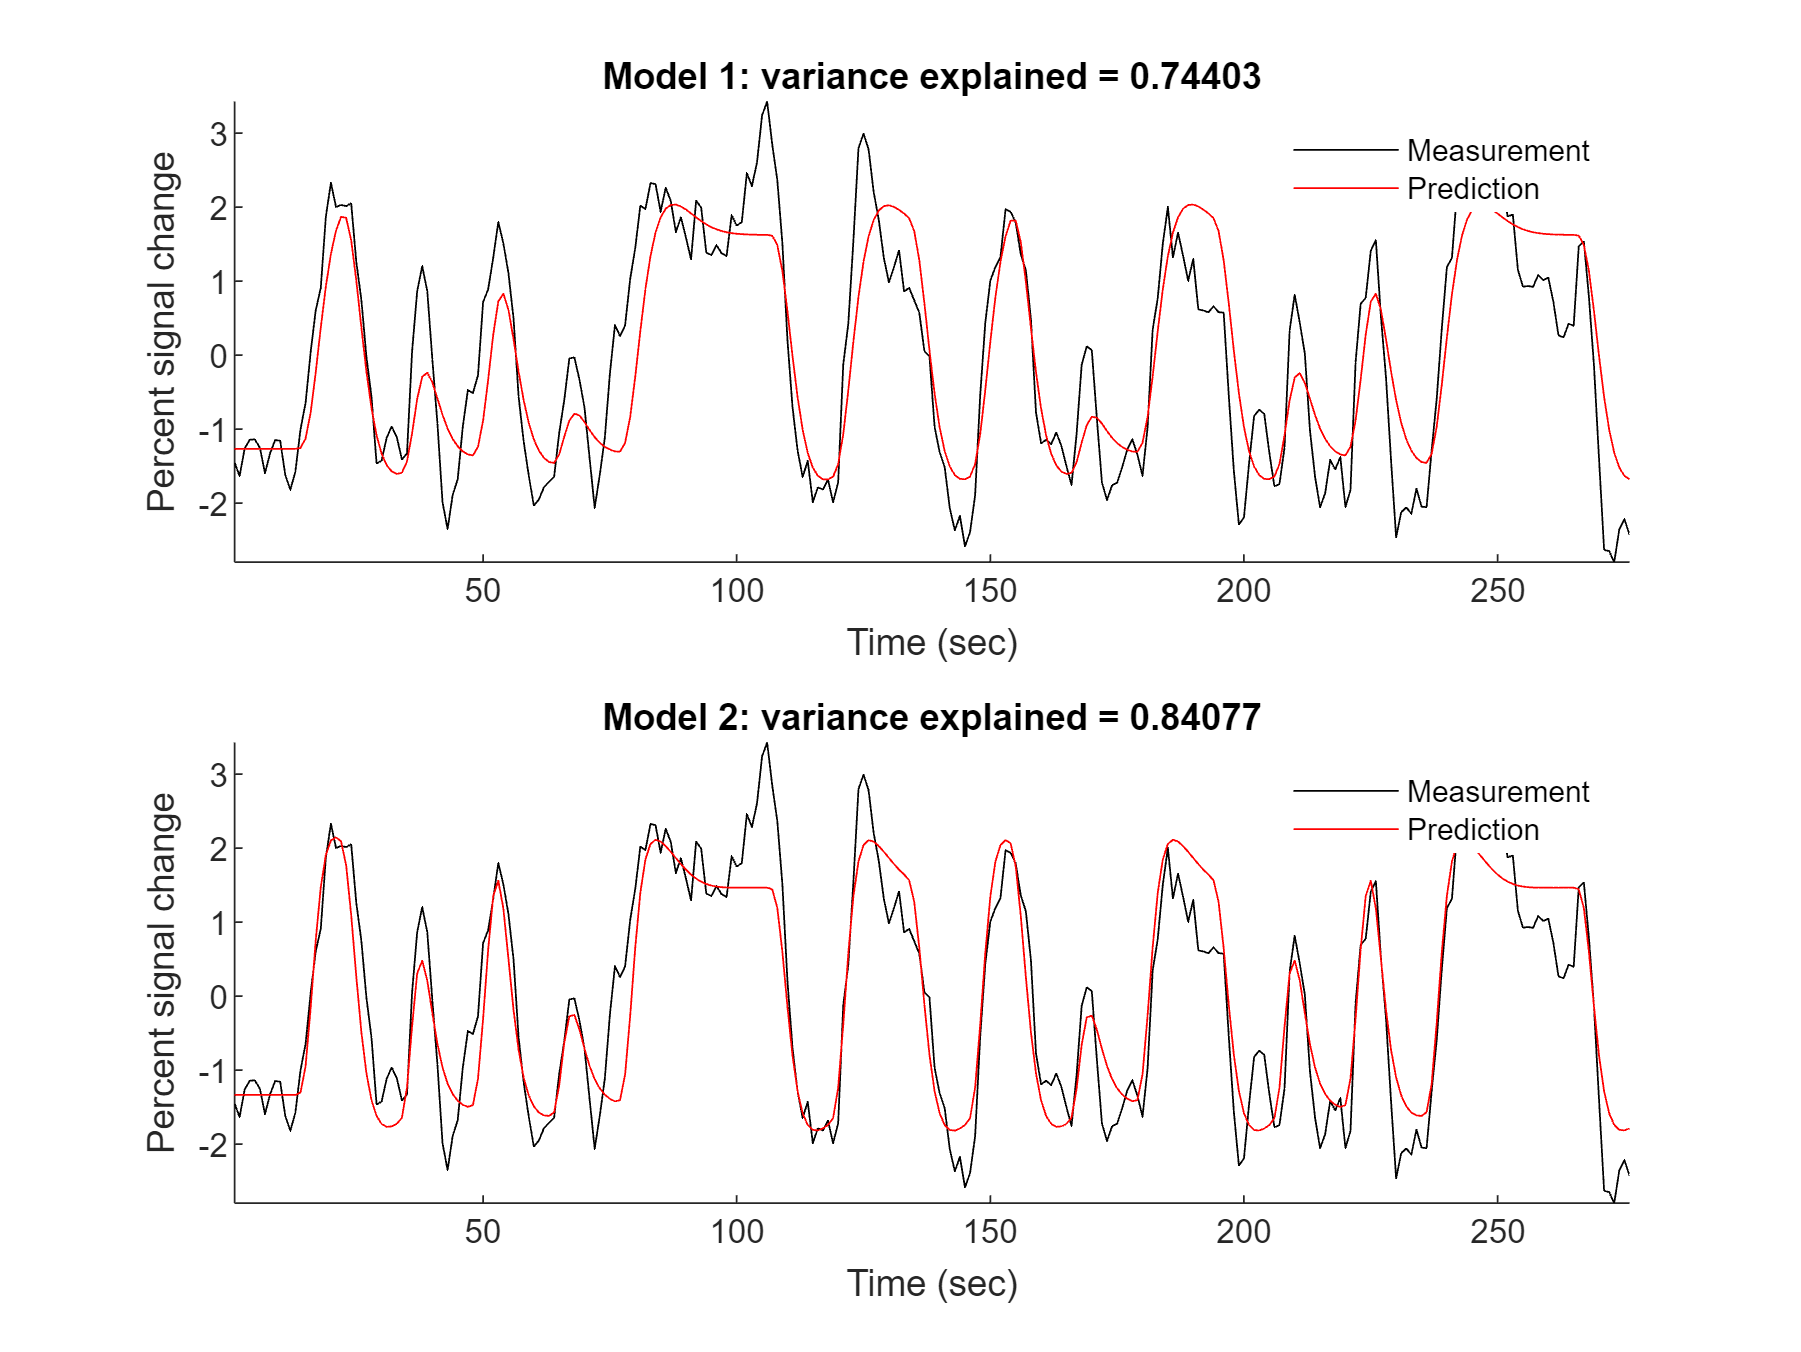

% Compare the fit of predicted timecourses to the measured timecourse
% Now let's plot the measured vs. predicted responses for each condition
figure('Color','w','Units','norm','Position',[.3 .1 .6 .8]);
% On top let's plot the measured response vs. the prediction from model 1
subplot(2,1,1); hold on;
plot(data,'k');
plot(tSeriesPredicted,'r');
axis tight;
title(['Model 1: Variance explained = ' num2str(varExp)],'FontWeight','bold');
xlabel('Time (sec)');
ylabel('Percent signal change');
legend('Measurement','Prediction'); legend boxoff;
% And on bottom the measured response vs. the prediction from model 2
subplot(2,1,2); hold on;
plot(data,'k');
plot(tSeriesPredicted2,'r');
axis tight;
title(['Model 2: Variance explained = ' num2str(varExp2)],'FontWeight','bold');
xlabel('Time (sec)');
ylabel('Percent signal change');
legend('Measurement','Prediction'); legend boxoff;

**Question 1**

Model 2 explains slightly more variance in the signal than Model 1, which means that the prediction generated from Model 2 was closer to the actual data than Model 1's prediction. Visually compare the fit between the measurement and predictions from the two models and comment on which aspects of the predicted response differ (e.g., the rise, peak, or fall).

**Question 2**

Fit the two GLMs again using an alternative HRF, and report how much variance is explained by Model 1 and Model 2. You can do so by commenting out the default HRF function in the HRF section, uncommenting one of the alternate models, and rerunning the script. Be sure to report which HRF you used and the variance explained by each model. 